## 测试函数

山东理工大学 数学院 周世祥

## Rastrigin多峰函数


$$$$

$$f(x_1,x_2)=20+(\frac{x_1}{30}-1)^2+(\frac{x_2}{30}-1)^2-10[cos 2\pi(\frac{x_2}{20})-1]\\

-100\leq x_1,x_2\leq 100$$


每种算法运行100次，观察全局最优解成功率，耗时。

f =@(x)20+(x(1)/30-1)^2+(x(2)/20-1)^2-10*(cos(2*pi*(x(1)/30-1))+cos(2*pi*(x(2)/20-1)))

f = 包含以下值的 function_handle :
    @(x)20+(x(1)/30-1)^2+(x(2)/20-1)^2-10*(cos(2*pi*(x(1)/30-1))+cos(2*pi*(x(2)/20-1)))


% 目标函数
A=[];B=[];Aeq=[];Beq=[];xm=-100*ones(2,1);xM=-xm;
F1=[];F2=[];F3=[];F4=[];
tic

for  i=1:100 ,x0=100*rand(2,1);
    %运行各种求解函数
    %[x,f0]=ga(f,2,A,B,Aeq,Beq,xm,xM);F1=[F1;x,f0];
    
    
    % [x,f0]=patternsearch(f,x0,A,B,Aeq,Beq,xm,xM);F2=[F2;x',f0];
     [x,f0]=particleswarm(f,2,xm,xM);F3=[F3;x,f0];
     %[x,f0]=simulannealbnd(f,x0,xm,xM);F4=[F4;x',f0];
end

Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.
Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.
Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.
Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.
Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.
Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.
Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxSta

toc

历时 2.613878 秒。



%i1=length(find(F1(:,3)<1e-5))
%i2=length(find(F2(:,3)<1e-5))
i3=length(find(F3(:,3)<1e-5))

i3 =     91


%i4=length(find(F4(:,3)<1e-5))

### Griewangk基准函数


$$min_x(1+\sum_{i=1}^n\frac{x_i^2}{4000}-\prod_{i=1}^ncos\frac{x_i}{\sqrt{i}}),x_i\in[-600,600]$$


n=50; %50个决策变量
f=@(x) 1+sum(x.^2/4000)-prod(cos(x(:)./[1:n]'));

A=[];B=[];Aeq=[];Beq=[];xm=-600*ones(n,1);xM=-xm;

F1=[];F2=[];F3=[];F4=[];
tic
for i =1:100,x0=600*rand(n,1)
    
    %[x,f0]=ga(f,n,A,B,Aeq,Beq,xm,xM);F1=[F1;f0];
    % [x,f0]=patternsearch(f,x0,A,B,Aeq,Beq,xm,xM);F2=[F2;f0];
     [x,f0]=particleswarm(f,n,xm,xM);F3=[F3;f0];
     %[x,f0]=simulannealbnd(f,x0,xm,xM);F4=[F4;f0];
    
end

x0 = 	1.0e+02 *

   5.547331193932800
   5.546182297849493
   1.649474442043273
   2.105319982951498
   1.815931194221220
   5.366023347889880
   0.817771290062103
   1.435676993119801
   5.094395427436423
   5.590798241034586


Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


x0 = 	1.0e+02 *

   1.875988002997825
   1.315736766694066
   3.145221160518761
   0.960491069557068
   3.377634121936497
   3.164819611808598
   1.141435455661418
   1.067963962541443
   2.024518018855858
   5.707992434471607


Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


x0 = 	1.0e+02 *

   3.183765959376841
   4.622508980191669
   4.586419955896582
   4.470335954072143
   1.120302125988152
   4.242961333239640
   4.914059958956343
   5.105794977592620
   0.099429168343043
   3.064673912341570


Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


x0 = 	1.0e+02 *

   4.292248808790005
   2.633582841925435
   4.622361944426167
   2.264524518304025
   4.301649055907674
   5.580495407124122
   4.183633595299176
   0.158030681038847
   0.614333111348885
   4.078501374964192


Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


x0 = 	1.0e+02 *

   1.303414611751909
   3.080992359855951
   5.567076632088729
   0.246781111693407
   4.527018482285016
   2.065217918207751
   0.813456559057091
   1.139017086728033
   2.056552139096237
   3.022287301041394


Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


x0 = 	1.0e+02 *

   3.711868462866286
   0.175640335408165
   1.903342330337965
   1.973545750045948
   1.370475975568087
   2.095999105470813
   5.418108984696563
   2.954055890721942
   3.409147843624845
   3.690269027996258


Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


x0 = 	1.0e+02 *

   4.165387472246481
   1.676882891550114
   1.402131374261506
   2.647449287790715
   0.866171307670516
   4.182884046125093
   5.718750009740288
   5.932980985258304
   1.670290590603546
   0.518693911748409


Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


x0 = 	1.0e+02 *

   2.579809951344015
   4.378433790457319
   3.010237552857478
   3.870362448870143
   3.361347863155690
   2.771782546163872
   5.843293232518424
   0.948564654258646
   4.845227611864885
   4.237396035538186


Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


x0 = 	1.0e+02 *

   3.657054593237108
   3.009501692242022
   2.212427357112225
   2.127897217193179
   4.429996173036788
   2.590686451558010
   1.477219290158911
   4.700093690161681
   1.274623979921658
   4.687673559192824


Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


x0 = 	1.0e+02 *

   0.202185458783683
   3.379180566737678
   0.240264009114753
   1.157012305327775
   2.091505532060249
   0.021364759377489
   1.807129910805236
   0.447173526195624
   4.768209829809314
   0.296423185108626


Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


x0 = 	1.0e+02 *

   1.723070473070977
   4.632487645486887
   2.039386232966326
   5.367716678756039
   5.050969446753100
   5.576140890167433
   1.397397633150373
   3.835622695127094
   2.799000489380264
   3.638297743066918


Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


x0 = 	1.0e+02 *

   1.885092452131160
   3.336042262505829
   0.802546753868496
   4.282052872509333
   1.959676353953606
   3.657058598129603
   3.803921074309776
   5.272457898251434
   0.010592286327671
   1.419250701428308


Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


x0 = 	1.0e+02 *

   4.107234306153853
   0.064179189120637
   0.766172236791256
   3.229210109099492
   4.016164259761141
   3.295451107542874
   1.315312967852448
   5.405097569764729
   4.363954529507996
   0.593881382929160


Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


x0 = 	1.0e+02 *

   3.651565891657762
   4.014346759748263
   1.698947260403072
   4.853325550409911
   4.397345590339676
   3.070609997536923
   2.113004635544891
   2.667780602254380
   1.209718783475735
   3.577330249205751


Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


x0 = 	1.0e+02 *

   4.948081004176086
   5.734756292618431
   5.047529273454705
   0.093219393048078
   0.227048789199660
   4.159412821306373
   1.850842494992947
   2.740934341161470
   1.026946166649473
   0.510203700902909


Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


x0 = 	1.0e+02 *

   2.151408171473296
   5.893302538191367
   5.228038611129609
   1.871147312149277
   1.303658373171424
   3.691129689566758
   4.305802861109146
   2.580847518408320
   5.223033911445306
   3.554691227868150


Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


x0 = 	1.0e+02 *

   0.871158055539377
   0.771070635893609
   2.598024953195441
   3.641508469565137
   0.899449355097738
   1.122692050215238
   5.017140933057502
   2.428527476271964
   3.449505904851011
   2.083694534692582


Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


x0 = 	1.0e+02 *

   4.304047073498148
   5.453975679486732
   5.517267446455016
   1.723866146399552
   0.616676704391580
   3.282931242592673
   3.025042508113165
   3.636461055332404
   2.764445723513043
   5.072644627329848


Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


x0 = 	1.0e+02 *

   3.629747250115748
   1.615407527156571
   3.389087313833043
   5.145900778139872
   4.867651385491048
   2.677326910817522
   5.153489320347102
   4.735179394061674
   1.390233768692831
   3.833811729736506


Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


x0 = 	1.0e+02 *

   3.822900857614167
   2.728220077138221
   5.669361954965783
   5.570248126390875
   2.597236848381173
   0.454934370953667
   4.091581258937379
   3.743330603396527
   2.324280689765797
   0.046141307468142


Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


x0 = 	1.0e+02 *

   4.124669654502953
   4.255544581521652
   3.421798043763325
   5.416752486555918
   0.509794704620436
   2.155951564850637
   4.233262435712616
   1.211886215487492
   1.705887812917540
   1.905922399371739


Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


x0 = 	1.0e+02 *

   4.614195922352490
   4.576289623726629
   5.358398421723013
   1.775521167152271
   0.540143638964089
   2.560271600518577
   4.027084982373870
   0.132794522402798
   1.619790055730083
   5.671029452852688


Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


x0 = 	1.0e+02 *

   1.754433659062997
   2.880775475323738
   3.781695399999192
   1.726111886404324
   2.622672795346821
   1.095367185606475
   2.569141197205860
   2.288394062575083
   2.916367475947415
   1.297013649195374


Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


x0 = 	1.0e+02 *

   4.123179883279244
   4.793442805535296
   4.223677456870558
   5.935799389480523
   2.651719665484504
   3.560911685226551
   0.698626945138113
   4.804898580107613
   4.629891060426269
   2.322474814550657


Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


x0 = 	1.0e+02 *

   0.331757311278364
   1.866241998592480
   0.168386833808051
   4.691718405935188
   3.356969596196052
   1.028911815387230
   4.386963601779669
   4.571866834341352
   5.480239178447572
   2.386980961193224


Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


x0 = 	1.0e+02 *

   5.408118702588655
   0.143738774601046
   2.288858278781238
   0.551350069731570
   3.844002394655919
   1.273349145589789
   0.282123804443696
   3.163800134338555
   2.170384033059820
   1.552642105338066


Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


x0 = 	1.0e+02 *

   3.739749978261361
   0.036110793127278
   0.773807355371989
   0.539468109347790
   0.023642346047630
   0.150684722219721
   1.028653971789893
   2.584719034329716
   2.321555725503576
   2.951481042609706


Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


x0 = 	1.0e+02 *

   2.871234490001049
   2.482913802807040
   3.106594139300233
   3.952587503411926
   1.028786761524342
   3.137963651352063
   3.996844114841433
   5.113004080834404
   4.685644328670670
   4.069301910305015


Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


x0 = 	1.0e+02 *

   3.649025261922647
   5.856726635939789
   2.211496927251523
   4.024845018791464
   3.252370140110427
   1.758933330108106
   3.406596404140577
   0.078312970571979
   5.506392276022462
   1.890336118676703


Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


x0 = 	1.0e+02 *

   4.735566149736818
   0.741516144886300
   3.538381141705318
   4.166565930121031
   0.839134200417516
   1.509114376713961
   0.937190075125728
   3.734821280455511
   4.574061184043349
   4.206930475385444


Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


x0 = 	1.0e+02 *

   4.736430851678718
   5.196069859820131
   3.717543425021723
   0.027706731349750
   0.189656011305262
   1.664960718493579
   4.570841845620899
   2.338376394260618
   3.237746974394431
   1.754351935453581


Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


x0 = 	1.0e+02 *

   1.040989464350167
   0.788465461501702
   4.922526935415116
   5.264210162814309
   4.662714437011740
   4.485538127752471
   2.394381508851347
   5.673198520314239
   1.842810209861219
   2.441038138079448


Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


x0 = 	1.0e+02 *

   3.512084843625021
   0.962295790848339
   4.584316770486734
   3.620563730599904
   2.578900324098819
   0.945757794096027
   3.661642337386591
   3.457877909305527
   1.731796588110739
   3.927019099012942


Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


x0 = 	1.0e+02 *

   3.979893971432113
   0.045045031635188
   1.056205159489449
   2.895765977458759
   0.252370981409630
   2.365715876843151
   0.076957239872351
   1.068324619438410
   4.925053730025397
   3.868097710538149


Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


x0 = 	1.0e+02 *

   5.074457506440837
   3.450511147354062
   0.647586941758708
   3.681577235623635
   3.483557599134558
   5.355133620369595
   0.056350792586929
   5.519864086007751
   1.943153720086560
   5.906260174505888


Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


x0 = 	1.0e+02 *

   4.803852499555114
   1.060878603547669
   3.620078490466940
   5.404545272691158
   0.438024632392964
   4.505017209902323
   4.737744189520733
   4.853782475060201
   1.738917650066854
   0.258482386204826


Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


x0 = 	1.0e+02 *

   2.302749464963518
   0.368445382796476
   0.811239191916842
   3.034995378952880
   3.311642627646015
   1.129280153021180
   0.490167930969172
   5.934774122828891
   2.635949010987098
   4.065558151138212


Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


x0 = 	1.0e+02 *

   0.828820532948062
   5.995276119507273
   2.866629951044601
   1.286766434012818
   5.334421229017900
   3.488290430721043
   0.889284610279072
   2.207210536007322
   1.301608819376018
   2.454346373141209


Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


x0 = 	1.0e+02 *

   1.423011358914750
   3.814307744693962
   5.955014108991461
   4.953660607436938
   3.044974705590429
   4.683060970770167
   5.158483713872206
   0.941469831007481
   0.307798178370737
   0.873191752141108


Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


x0 = 	1.0e+02 *

   3.358082858878849
   1.625463395540722
   1.758438728130696
   5.496391405032579
   2.904299894102122
   0.159024303902455
   1.606350539430785
   4.803819273224170
   3.453655886604905
   4.601625818728776


Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


x0 = 	1.0e+02 *

   4.126612790326414
   2.153442187190422
   0.890710451775035
   0.804492388738812
   5.342368941137294
   1.392153893916943
   1.531376995929618
   1.015379887587890
   4.689715340627579
   1.768504038929746


Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


x0 = 	1.0e+02 *

   3.337765057075891
   1.457864889645947
   1.063161554179123
   3.520441443101150
   5.639492670994794
   5.174950809037520
   0.097299959433014
   2.828664906564434
   1.847701054133928
   5.055375576531464


Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


x0 = 	1.0e+02 *

   2.098217962693284
   0.309383449394584
   1.756292744001435
   3.718777362061823
   0.215378493759929
   3.320224695855348
   5.180729895797976
   4.729760342845963
   3.095546624001685
   2.435634902878196


Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


x0 = 	1.0e+02 *

   3.312653573623736
   4.062013438955777
   3.602006305419654
   5.906680842379656
   0.398609998346412
   0.353538967620492
   5.781728333710412
   4.866394175865429
   4.194631111205362
   3.055053839074430


Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


x0 = 	1.0e+02 *

   3.906985714182495
   2.713078541894133
   0.245457768378160
   0.419333182487196
   4.591391260999550
   5.243855404157143
   5.143263550989036
   2.178392384703119
   4.151313423945444
   4.355352143298891


Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


x0 = 	1.0e+02 *

   4.763994061766227
   4.795733242719890
   4.796621320913096
   1.586469618679621
   2.215782590602310
   3.526023678341403
   4.494127960731932
   5.530989711792079
   5.319516983365085
   1.714858333302569


Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


x0 = 	1.0e+02 *

   1.350018088403508
   2.246221407472221
   5.164646632316556
   2.449185522251436
   1.397493544473276
   1.182595854217989
   3.378009210422214
   1.835465054336931
   0.106552415052738
   3.496109153910854


Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


x0 = 	1.0e+02 *

   2.591022116686131
   4.340982456610035
   1.953641990739846
   1.902529035927724
   3.012419632040733
   0.290811011476607
   1.148917469766577
   0.858657014482716
   2.040457482844847
   3.510570354786204


Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


x0 = 	1.0e+02 *

   4.483528362627251
   5.675834442629541
   5.808748679773437
   2.218295266030387
   3.313548587869402
   5.098602545843656
   0.403005910435172
   2.838737908868371
   3.360166682287160
   2.753795858918734


Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


x0 = 	1.0e+02 *

   5.536620474189513
   5.995891816679496
   4.361326629532235
   3.047660429663479
   1.665688064707064
   5.228936407821510
   4.606544613117329
   5.638158886356340
   5.664225711424126
   4.742983229264158


Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


x0 = 	1.0e+02 *

   0.291944317225090
   1.931037337763448
   0.983851853303973
   5.364972904862210
   1.772005729420749
   4.106058293319337
   5.555383499489364
   3.164681639023035
   5.960706115401085
   4.200282130398769


Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


x0 =    4.473343462673611
   4.010237884181298
   1.044584947770454
   5.954619500325248
   1.089695132150531
   0.120234094853835
   2.709012408010858
   3.088823243469061
   5.422067912342419
   4.160396231254673


Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


x0 =    5.574245831758126
   1.203427954850881
   1.007255550396338
   0.447773225331417
   3.573224291717251
   2.576627699401137
   0.421031298079655
   1.671031321974995
   5.495392736181995
   0.816601231960086


Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


x0 =    1.255039706791357
   2.917452346124989
   3.421398130884867
   0.997971572681978
   3.075839891758081
   2.380799957640547
   1.909009641918010
   2.075838056183577
   1.833407556154770
   4.044451578601294


Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


x0 =    3.122865359730772
   3.473648157933996
   0.809772934646271
   0.473744193976479
   5.060428540934427
   1.613131938847917
   3.304758257082202
   0.992690051383301
   1.761024200768016
   0.478170664285417


Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


x0 =    0.745358798756814
   3.108834520412490
   1.210169086292720
   5.638170940709646
   1.169798732698156
   1.708256704331656
   0.278121428148522
   1.359941699849909
   3.129871439504989
   0.664980309740922


Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


x0 =    3.490358262059325
   3.642774322809230
   1.621565145312098
   3.358339410249557
   2.606295862596964
   1.962007450788922
   2.805596852171592
   3.122145761401114
   3.106876766109382
   3.921630306695773


Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


x0 =    2.694914976157460
   1.388905615328519
   2.871968852932288
   4.855040304549616
   2.945552068720514
   1.544098581445397
   4.334496545477922
   3.474933991043632
   4.115548446282603
   0.764351535640869


Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


x0 =    1.843895570611268
   5.588076475319283
   2.243702277202652
   0.509739607862124
   0.277578300600787
   0.313876872460062
   1.375861068376958
   2.577657321108333
   0.630346152858916
   4.946746774421974


Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


x0 =    5.694786599138951
   3.088950672610987
   2.252906611340871
   1.830267930326823
   0.842688336555219
   2.487237287955307
   2.494060202223671
   2.553983756676732
   5.264172010419936
   4.205356891902880


Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


x0 =    0.251278910451364
   4.925935956051649
   4.423446350005678
   5.315860364622156
   5.301116802188419
   5.361264955821910
   1.540857419097095
   2.789767811668528
   2.657235159915007
   1.296118872786601


Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


x0 =    0.282810776878984
   4.611144680857586
   1.640605687836348
   1.537520538427487
   4.924400625825625
   0.889002967745278
   0.705264510281887
   1.777503704524285
   0.400039485388402
   2.633322851860599


Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


x0 =    4.017145937366297
   4.923486067100326
   4.381435321797624
   5.643090689612952
   0.371705656644544
   4.796336592691619
   2.936382714943004
   2.005131959573048
   3.750639416097848
   3.497509634678017


Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


x0 =    2.593831864421713
   3.002666343182251
   3.503157799195771
   1.138510756797420
   4.270014047051612
   0.253407869390329
   0.205110617027628
   5.663013062130961
   4.859681382165864
   0.567590863637286


Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


x0 =    5.837855659458606
   0.054911039630672
   1.892463583647215
   1.991171440608398
   4.985880109544379
   1.319049708760023
   5.269352514636783
   5.347439891394909
   4.977585434819699
   5.905756674733807


Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


x0 =    3.343127424372494
   3.606091138567337
   1.274753995075696
   4.062863879901642
   1.135500475451460
   1.801971654303647
   1.696548914614398
   0.405398131226738
   2.865184873671350
   0.438536230214299


Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


x0 =    1.554251272091712
   2.938064790426409
   4.970180984163901
   4.322069305441630
   1.886516618045116
   5.289029353316006
   5.796465190591590
   4.103502955724182
   3.985821531010438
   4.600349540360573


Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


x0 =    3.406992769571590
   5.844917963731249
   5.220763928962316
   4.303671685108138
   4.354155582358628
   4.754908464791706
   3.038183549074585
   5.467976347862276
   3.690922363721354
   4.353027768018261


Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


x0 =    1.461581383855449
   2.396414759343413
   5.350020867604257
   1.837212793278813
   0.531899217453409
   0.746788788764822
   2.431023168693291
   3.832726255812646
   4.634884594749079
   2.061030843461896


Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


x0 =    5.371226920389216
   0.625454647154589
   1.037235749471106
   3.763608623049148
   2.581281984850635
   0.350728743627258
   1.853422376396295
   0.326184516797791
   3.380817469283711
   3.084916451563259


Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


x0 =    1.055103583213929
   3.344879734222646
   1.746184573597909
   5.256332087315578
   5.654686197898302
   0.344725722534963
   3.468336822912911
   1.407096300809022
   2.011900218420336
   0.994131741406168


Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


x0 =    5.952469392124119
   5.665766816586093
   4.293038527164146
   5.879732342944187
   0.168101534306055
   3.285989160393733
   5.108528517645740
   0.630365428134786
   4.975761103203894
   2.366546498531010


Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


x0 =    5.704484910305077
   4.412267030422973
   2.416083120705640
   1.482200284572287
   4.522833717981310
   5.937448543830426
   3.974536202961574
   3.744054541595196
   3.533042917555371
   2.508555046650738


Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


x0 =    1.456109639042386
   5.008103679140249
   3.890901562578100
   4.761978082380273
   3.908051927050761
   2.627356321103634
   3.968049567747427
   2.009616541788073
   0.001731370514672
   3.542371982380808


Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


x0 =    3.460637421737589
   5.426301662402341
   3.831308289964812
   5.476299587088797
   0.016957562408245
   5.122085881960815
   5.099065257604184
   3.912574121884312
   1.016543939026805
   2.093915685475404


Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


x0 =    5.259559264113586
   0.051746156405856
   0.010702149535418
   1.575053998172252
   4.956254712390815
   4.920348709951676
   4.893625167620078
   4.091270602102851
   3.931564111143012
   0.621624728018095


Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


x0 =    2.569636779827087
   0.452022258061136
   3.165462492467864
   3.581183886713288
   4.466595005316820
   2.108204942016988
   0.099397473523258
   4.419284561480566
   3.357996976673293
   3.402341016928469


Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


x0 =    3.831371524921404
   1.155973844759629
   1.295276612397863
   4.214528784030050
   0.637551046673407
   1.305939300458230
   4.248963062075724
   4.769690481993307
   3.494801694444227
   0.689913926076706


Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


x0 =    0.372214197910625
   3.186470184550572
   5.494020660400530
   1.470379451339944
   0.714052707245451
   1.546782922134526
   4.796409694327451
   2.989130429044602
   1.677380980857005
   2.625653589869544


Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


x0 =    5.978984842102619
   3.712790787743494
   5.860657132116731
   0.312231558592965
   0.608397167586646
   0.044999661763272
   0.000223423305443
   3.875759187977637
   2.373778239589455
   5.159446323337558


Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


x0 =    2.450088073728231
   5.042802899973276
   0.854416848633220
   0.343304504975997
   3.138929039862033
   5.681448625136409
   1.429490082700675
   3.222605035778527
   0.263777456495045
   0.617518704668636


Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


x0 =    0.803422333595033
   0.649280150290166
   0.319719509416796
   1.996662760041173
   1.094389987842272
   0.440306357677913
   1.928104330691999
   5.048085276544850
   4.808970189206033
   5.520531819262747


Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


x0 =    4.404526893030927
   3.380256594634617
   2.686714401920306
   3.928014795135339
   0.368144810246885
   5.001152660454773
   4.813932468079551
   0.160329625004441
   3.851724322360842
   5.219508319883995


Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


x0 =    0.300245452256530
   0.805357207791359
   0.684311367485292
   1.919739855347587
   4.950395641926399
   0.222226938740001
   1.216233289940887
   1.661460034416069
   1.348436864104548
   3.158482586372978


Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


x0 =    0.005510592492572
   4.668094573211024
   5.915109160542187
   5.443519628322222
   0.244097128639494
   4.886759207725475
   5.889375262245678
   1.868877301478310
   1.169069413622496
   1.941229871122021


Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


x0 =    4.908035447560675
   5.320895783695703
   5.681678939626931
   5.305205862993281
   0.157883582109600
   1.147808640422868
   2.497211496990751
   1.418971141552641
   2.879264918259408
   2.784445981848077


Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


x0 =    0.558766356131833
   1.503357503102378
   5.567877133896527
   4.673072938738726
   0.456235878683146
   4.910444533290834
   5.698529405653850
   4.869616790103397
   4.198955434260171
   5.250424960330370


Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


x0 =    0.721375555202414
   0.826479670589844
   5.066182739208344
   2.279289473933221
   5.038794591148743
   1.508509027267606
   0.442590884671853
   4.115867831648361
   0.063662912387209
   0.490081040079386


Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


x0 =    5.087724093915855
   3.743212740200509
   1.128451722368707
   4.192077849979068
   4.345758216713167
   4.462213505143436
   2.886267465930545
   5.600735962872291
   2.457206973023496
   0.949495641047624


Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


x0 =    3.574916410137416
   5.416226217849603
   3.836648158003688
   4.915914056050049
   2.085635993212267
   4.220208682360600
   2.584713379518245
   0.553806867578031
   4.623693379022267
   3.453913865268553


Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


x0 =    5.664045613752532
   3.860852295741261
   1.897391776972916
   1.456624358071368
   2.132502477055038
   5.817080335415283
   4.157729733688762
   5.746860216027060
   0.775204715165319
   5.989309580342864


Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


x0 =    3.281123353620696
   0.063025035000966
   4.964939129019487
   4.866929943411325
   2.704235568953723
   1.410450005286637
   4.433421637428065
   1.827401593604062
   3.961580260041180
   0.682767351499505


Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


x0 =    0.508972586393126
   1.835932053059837
   2.799845146739210
   0.702306051035011
   0.063694462091541
   1.281780857350296
   0.656429858219935
   2.087376311835433
   1.992778656347954
   3.184423893493643


Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


x0 =    2.177350977403039
   5.813212303870420
   4.552169445627953
   0.248254701453214
   0.625819793392074
   5.057308010477263
   4.667007581136909
   5.719173554322002
   4.022639419669582
   3.555707851535264


Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


x0 =    4.226278257003404
   3.624505500735479
   1.049434559969357
   2.667036499728405
   0.071795117153048
   4.451720730863685
   4.990846256176366
   1.393617208294941
   0.581893740056162
   0.827062423860205


Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


x0 =    5.864896654634018
   2.921945791638967
   1.431828380664082
   4.913341572799305
   0.197892748464777
   3.223846426595437
   3.092293128616362
   1.130327903179131
   0.251458070211975
   0.950333034812364


Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


x0 =    4.644677674975836
   1.348984590945444
   1.822394969699337
   5.373761081998924
   0.650220419822704
   5.458956914726533
   0.676514241391972
   0.087434222891916
   1.130123588014388
   3.371830743013944


Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


x0 =    0.562756912031044
   1.966024976836289
   2.190194180764738
   4.826335508295842
   4.171065478515242
   4.423453166548327
   2.074068171007312
   0.397409472736515
   4.336898641871836
   2.630982043445203


Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


x0 =    3.660459801389969
   1.955165019696434
   2.608090217194510
   2.943115942559257
   4.580120936832898
   1.805130991287411
   5.921186810771755
   4.871618920217011
   4.076926942692399
   4.093704898536322


Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


x0 =    2.425279305397603
   0.579886914638365
   4.908913187892167
   3.370043572903813
   4.965308029741474
   5.386797679030349
   0.134395244602180
   0.136012758100319
   2.142191288409403
   4.492407567874576


Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


toc

历时 41.009270 秒。



% 最优解为全0
max(F4), max(F3)


ans =

     []



ans =    0.794034887857747


### 复制的非线性规划求解

非线性约束条件：

function [c,ceq]=c5mcpl(x)

ceq=[];

A1=sqrt((745*x(4)/x(2)/x(3))^2+16.91e6); B1=0.1*x(6)^3;

A2=sqrt((745*x(5)/x(2)/x(3))^2+157.5e6); B2=0.1*x(7)^3;

c=[-x(1)*x(2)^2*x(3)+27; -x(1)*x(2)^2*x(3)^2+397.5;

   -x(2)*x(6)^4*x(3)/x(4)^3+1.93; A1/B1-1100; 

   -x(2)*x(7)^4*x(3)/x(5)^3+1.93; A2/B2-850;

   x(2)*x(3)-40; -x(1)/x(2)+5; x(1)/x(2)-12;

   1.5*x(6)+1.9-x(4); 1.1*x(7)+1.9-x(5)];

目标函数：


$$min \, f(x) =0.7854*x(1)*x(2)^2*(3.3333*x(3)^2+14.9334*x(3)-43.0934)-1.508*x(1)*(x(6)^2+x(7)^2)+7.477*(x(6)^3+x(7)^3)+0.7854*(x(4)*x(6)^2+x(5)*x(7)^2);
$$


A=[];B=[];Aeq=[];Beq=[];
f=@(x)0.7854*x(1)*x(2)^2*(3.3333*x(3)^2+14.9334*x(3)-43.0934)-1.508*x(1)*(x(6)^2+x(7)^2)+7.477*(x(6)^3+x(7)^3)+0.7854*(x(4)*x(6)^2+x(5)*x(7)^2);

xm=[2.6,0.7,17,7.3,7.3,2.9,5];
xM=[3.6,0.8,28,8.3,8.3,3.9,5.5];
[x,f0]=fmincon(f,rand(7,1),A,B,Aeq,Beq,xm,xM,@c5mcpl)


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


x =    3.500000006636445
   0.700000000308885
  17.000000011596669
   7.300000215221772
   7.715320005042021
   3.350540957339616
   5.286654468041168


f0 =      2.994424479756736e+03





%遗传算法
xx=[]


xx =

     []



for i=1:7
    tic 
    [x,x0,flag]=ga(f,7,A,B,Aeq,Beq,xm,xM,@c5mcpl)
    toc
    if flag==1
        xx=[xx;x f0];
    
    end
end

Optimization terminated: average change in the fitness value less than options.FunctionTolerance
 and constraint violation is less than options.ConstraintTolerance.


x =    3.499307012557983   0.700000000000000  17.000006908649876   7.300024392948004   7.714347230157927   3.350558474642386   5.286658301652233


x0 =      2.994139241155538e+03


flag =      1


历时 6.347366 秒。


Optimization terminated: average change in the fitness value less than options.FunctionTolerance
 and constraint violation is less than options.ConstraintTolerance.


x =    3.499337138055132   0.700000000000000  17.000000785166478   7.300052260774426   7.714350489192857   3.350557197013762   5.286678882578051


x0 =      2.994163080211917e+03


flag =      1


历时 6.932386 秒。


Optimization terminated: average change in the fitness value less than options.FunctionTolerance
 and constraint violation is less than options.ConstraintTolerance.


x =    3.499306316180380   0.700000716459022  17.000019020482220   7.300017151046177   7.714333848290782   3.350594090526433   5.286663887241117


x0 =      2.994156564414514e+03


flag =      1


历时 6.841788 秒。


Optimization terminated: average change in the fitness value less than options.FunctionTolerance
 and constraint violation is less than options.ConstraintTolerance.


x =    3.499317615478162   0.700000000000000  17.000030117829496   7.300001247436671   7.714361790363297   3.350568907719319   5.286680338523436


x0 =      2.994164186954588e+03


flag =      1


历时 6.169772 秒。


Optimization terminated: average change in the fitness value less than options.FunctionTolerance
 and constraint violation is less than options.ConstraintTolerance.


x =    3.499345131481935   0.700005229302753  17.000057686516506   7.300032798236215   7.714349895767690   3.350558087152698   5.286662278329423


x0 =      2.994189168432489e+03


flag =      1


历时 6.167973 秒。


Optimization terminated: average change in the fitness value less than options.FunctionTolerance
 and constraint violation is less than options.ConstraintTolerance.


x =    3.499320799387414   0.700001833184744  17.000006751000530   7.300025555049562   7.714344516686969   3.350559145885431   5.286662951111794


x0 =      2.994155985633152e+03


flag =      1


历时 7.251440 秒。


Optimization terminated: average change in the fitness value less than options.FunctionTolerance
 and constraint violation is less than options.ConstraintTolerance.


x =    3.499302564458190   0.700000000000000  17.000015701674656   7.300039720659272   7.714365598727852   3.350550631870008   5.286672859785385


x0 =      2.994146799506752e+03


flag =      1


历时 12.028220 秒。


## 神经网络拟合

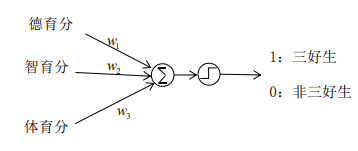

                          神经网络分类器

     做一个简单的评三好生的神经 网络模型，假如如果手头上有一些三好生和非三好生的成绩数据，我们可 以把这些样本“喂”给模型，经过一段时间后，网络就可以学习到三个权 值参数的信息。下一步我们就可以用这个学到的网络来评判是否三好生。

下面是一个神经网络拟合问题，有一个通用逼近定理，任何非线性函数都可以用一个神经网络来拟合！

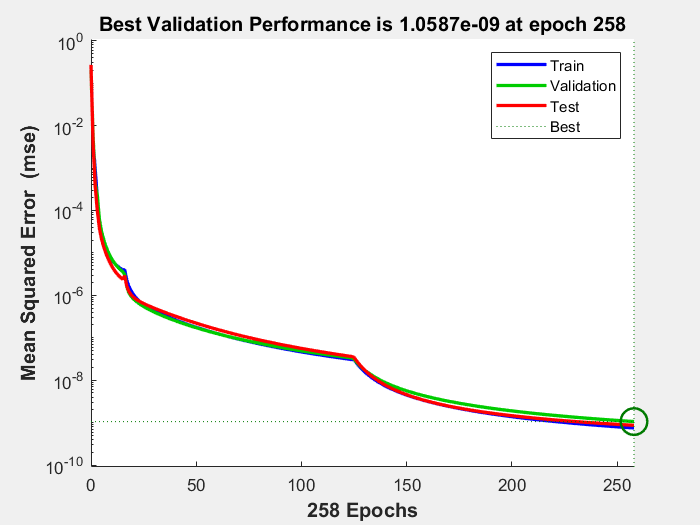

x = 0:0.05:10;
y=0.12*exp(-0.213*x)+0.54*exp(-0.17*x).*sin(1.23*x);

net=fitnet(5);

net.trainParam.epochs=1000;
[net,b]=train(net,x,y);

plotperform(b)

x0=[0:0.1:10];
y0=0.12*exp(-0.213*x0)+0.54*exp(-0.17*x0).*sin(1.23*x0);
y1=net(x0)

y1 =    0.120002927083594   0.182634862177425   0.242106070313422   0.297631963040401   0.348486627333586   0.394022491722914   0.433686195907111   0.467030199615368   0.493720063792444   0.513537677667970   0.526380951916948   0.532260634859921   0.531294939393403   0.523702612318021   0.509794963085850   0.489967226344669   0.464689489917487   0.434497298767277   0.399981959992906   0.361780529906099   0.320565460503311   0.277033912243741   0.231896792215507   0.185867638902759   0.139651534321151   0.093934270520315   0.049372022720943   0.006581781918604  -0.033867224031091  -0.071460936087988


plot(x,y,'o',x0,y0,x0,y1,':');



### 再一个例子

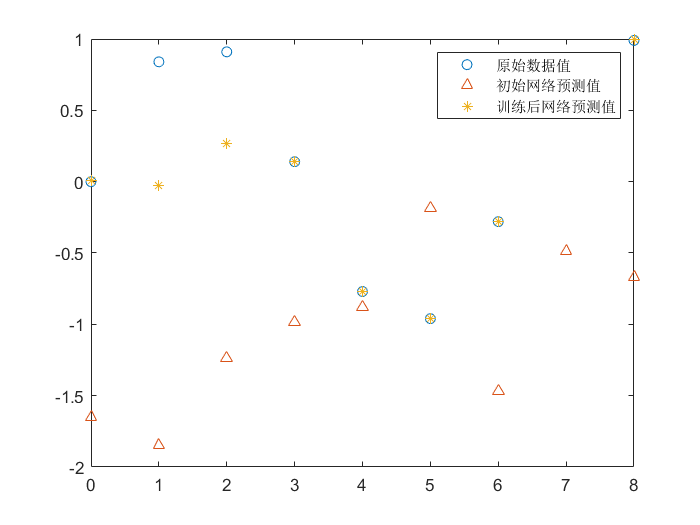

clc 
clear 
close 
x = [0 1 2 3 4 5 6 7 8];  % 样本属性值 
t = [0 0.84 0.91 0.14 -0.77 -0.96 -0.28 0.66 0.99]; %样本的目标标签值 
net = feedforwardnet(10);  %定义神经网络一层隐含层，且神经元数量为10个 
net = configure(net,x,t); %利用构建的网络，对网络各参数进行初始化赋值，形成初始网络 
y1 = net(x);  %初始网络对输入进行计算后的输出 
net = train(net,x,t); %对国建的神经网络进行训练，输出训练完成的网络 
y2 = net(x); %训练完成后的网络对输入进行计算后的输出 
plot(x,t,'o',x,y1,'^',x,y2,'*') %对三者数据进行绘图 
legend('原始数据值','初始网络预测值','训练后网络预测值')

### google神经网络在线测试平台演示

PlayGround 是一个在线演示、实验的神经网络平台，是一个入门神经 网络非常直观的网站。这个图形化平台非常强大，将神经网络的训练过程 直接可视化。网址是：http://playground.tensorflow.org/。 PlayGround 页面如图所示，主要分为 DATA（数据），FEATURES（特征）， HIDDEN LAYERS（隐含层），OUTPUT（输出层）

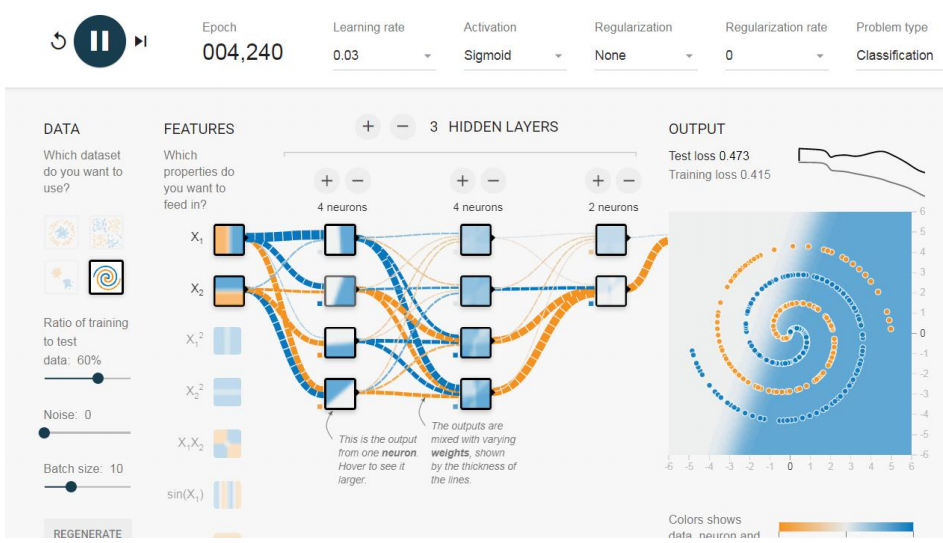

图中点被标记为两种颜色,深色为正(电脑屏幕颜色为蓝色)，浅色为负 (电脑屏幕颜色为黄色)，表示要区分的两类数据。 上图我们选了最复杂的螺旋型数据来分类，输入为待分类点的横，纵 坐标两个特征，隐藏层有两个，层之间的连线颜色代表权重正负，层与层 之间的连线粗细表示权重的绝对值大小，训练开始后，我们可以把鼠标放 在线上查看权值，也可以点击修改。

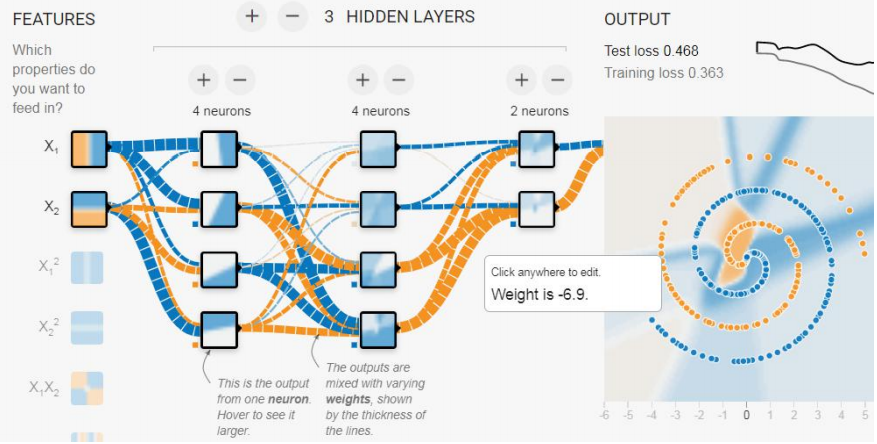

我们设置，两个隐藏层，用 sigmoid 激活函数，训练的批大 小为 10，学习率为 0.01，在训练集上的损失是 0.363，在测试集上的损失为 0.468，我们可以调整特征的个数，迭代次数、学习速率、激活函数、隐藏 层数和隐藏节点的个数等超参数，动态地观察分类效果。PlayGround 还提 供了非常灵活的数据配置，可以调节噪声、训练数据和测试数据的比例和 Batch size 的大小。 一般来讲，隐含层越多，衍生出的特征类型也就越丰富，对于分类的 效果也会越好，但不是越多越好，层数多了训练的速度会变慢，同时收敛 的效果不一定会更好，层数和特征的个数太多，会造成训练越困难。